% Rocky_closed_loop_poles_23.m
%
% 1) Symbolically calculates closed loop transfer function of a disturbannce
% rejection PI control system for Rocky.
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this, the control constants can be found exactly
%
% 5) Plot impulse and step response to see closed-loop behavior.
%
% based on code by SG. last modified 2/25/23 CL
clear all;
close all;
syms s a b l g Kp Ki % define symbolic variables
Hvtheta = -s/l/(s^2-g/l); % TF from velocity to angle of pendulum
K = Kp + Ki/s; % TF of the PI angle controller
M = a*b/(s+a) % TF of motor (1st order model)

$$M = \frac{a\,b}{a+s}$$

% M = 1; % TF without motor
%
%
% closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K) % use this for no motor feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)}-1}$$

% pretty(simplify(Hcloop)) % to display the total transfer function

% Substitute parameters and solve
% system parameters
g = 9.81;
w_n = 4.88;

l = g/(w_n^2)%22*2.54/100 %effective length

l = 0.4119

a = 1/0.0459; %nominal motor parameters
b = 0.00323; %nominal motor parameters
Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{565592\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{3310875\,\left(s^{2}-\frac{14884}{625}\right)\,\left(s+\frac{10000}{459}\right)}+1}$$

% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc.

% -zeta * wn +/- i*wn-sqrt(1 - zeta^2)
zeta = 0.8

zeta = 0.8000

p1 = -zeta * w_n + w_n*1i*sqrt(1 - zeta^2) % dominant pole pair

p1 = -3.9040 + 2.9280i

p2 = -zeta * w_n - w_n*1i*sqrt(1 - zeta^2) % dominant pole pair

p2 = -3.9040 - 2.9280i

p3 = -5

p3 = -5


% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

$$tgt\_char\_poly = \left(s+5\right)\,\left(s+\frac{488}{125}-\frac{366}{125}\,\mathrm{i}\right)\,\left(s+\frac{488}{125}+\frac{366}{125}\,\mathrm{i}\right)$$

npoly = 3

npoly = 3

% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = 981\,\left(459\,s+10000\right)\,\left(625\,s^{2}-14884\right)$$

$$d = 48075320\,\mathrm{Ki}-6701952636\,s+48075320\,\mathrm{Kp}\,s+6131250000\,s^{2}+281424375\,s^{3}-146012040000$$

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccc} 48075320\,\mathrm{Ki}-146012040000 & 48075320\,\mathrm{Kp}-6701952636 & 6131250000 & 281424375 \end{array}\right)$$

% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccc} \frac{565592\,\mathrm{Ki}}{3310875}-\frac{238144}{459} & \frac{565592\,\mathrm{Kp}}{3310875}-\frac{14884}{625} & \frac{10000}{459} & 1 \end{array}\right)$$

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccc} \frac{14884}{125} & \frac{39284}{625} & \frac{1601}{125} & 1 \end{array}\right)$$

% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:npoly-1) == coeffs_tgt(1:npoly-1), Kp, Ki)

solutions = struct with fields:
    Kp: 2940057/5795
    Ki: 2412279/646


% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 507.3437

Ki = double(solutions.Ki)

Ki = 3.7342e+03

% reorder coefficients for the check polynomial
for ii = 1:length(coeffs_denom)
chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end
closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), npoly )

$$closed\_loop\_poles = \left(\begin{array}{c} -18.8\\ -1.5-2.02\,\mathrm{i}\\ -1.5+2.02\,\mathrm{i} \end{array}\right)$$

% Plot impulse response of closed-loop system
TFstring = char(subs(Hcloop));
% Define 's' as transfer function variable
s = tf('s');
% Evaluate the expression
eval(['TFH = ',TFstring]);

TFH =
 
  7.281e18 s^4 + 1.586e20 s^3 - 1.734e20 s^2 - 3.777e21 s
  -------------------------------------------------------
  7.281e18 s^4 + 1.586e20 s^3 + 4.576e20 s^2 + 8.669e20 s
 
Continuous-time transfer function.



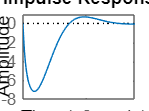

figure (1)
impulse(TFH); %plot the impulse reponse

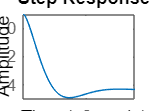

figure(2)
step(TFH) %plot the step response

# 5 Poles

close all
clear all
clc
% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/8/22 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 
% M = 1;                        % TF without motor
%
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

%  
% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback
Hcloop = 1/(1-Hvtheta*Mfb*K)    % use this for motor with feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{a+s}+1\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (Ki + Kp s)
  -------------------------------------------------------- - 1
        2          2    3                    2
  (- l s  + g) (a s  + s  + Ci a b + Jp a b s  + Ji a b s)




% Substitute parameters and solve
% system parameters
g = 9.81;
w_n = 4.88;

l = g/(w_n^2) %22*2.54/100 %effective length

l = 0.4119

a = 1/0.0459; %nominal motor parameters
b = 0.00323; %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{565592\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{3310875\,\left(s^{2}-\frac{14884}{625}\right)\,\left(\frac{19\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{270\,\left(s+\frac{10000}{459}\right)}+1\right)\,\left(s+\frac{10000}{459}\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 

% -zeta * wn +/- i*wn*sqrt(1 - zeta^2)
% zeta = 0.8;
% zeta2 = 0.9;
zeta = 0.8;
zeta2 = 0.75;

p1 = -zeta * w_n + 1i*w_n*sqrt(1 - zeta^2)    % dominant pole pair

p1 = -3.9040 + 2.9280i

p2 = -zeta * w_n - 1i*w_n*sqrt(1 - zeta^2)    % dominant pole pair 

p2 = -3.9040 - 2.9280i

p3 = -20

p3 = -20

p4 = -zeta2 * w_n + 1i*w_n*sqrt(1 - zeta2^2)    % dominant pole pair

p4 = -3.6600 + 3.2278i

p5 = -zeta2 * w_n - 1i*w_n*sqrt(1 - zeta2^2)     % dominant pole pair 

p5 = -3.6600 - 3.2278i


% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
% tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$tgt\_char\_poly = \left(s+20\right)\,\left(s+\frac{488}{125}-\frac{366}{125}\,\mathrm{i}\right)\,\left(s+\frac{488}{125}+\frac{366}{125}\,\mathrm{i}\right)\,\left(s+\frac{183}{50}-\frac{61\,\sqrt{7}\,\mathrm{i}}{50}\right)\,\left(s+\frac{183}{50}+\frac{61\,\sqrt{7}\,\mathrm{i}}{50}\right)$$

exp_tgt_char_poly = expand(tgt_char_poly)

$$exp\_tgt\_char\_poly = s^{5}+\frac{4391\,s^{4}}{125}+\frac{1272948\,s^{3}}{3125}+\frac{191869644\,s^{2}}{78125}+\frac{3036097856\,s}{390625}+\frac{886133824}{78125}$$


% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = 981\,\left(625\,s^{2}-14884\right)\,\left(323\,\text{Ci}+323\,\mathrm{Ji}\,s+323\,\mathrm{Jp}\,s^{2}+100000\,s^{2}+4590\,s^{3}\right)$$

$$d = 198039375\,\text{Ci}\,s^{2}-4716188892\,\mathrm{Ji}\,s-4716188892\,\text{Ci}+198039375\,\mathrm{Ji}\,s^{3}-4716188892\,\mathrm{Jp}\,s^{2}+198039375\,\mathrm{Jp}\,s^{4}+480753200\,\mathrm{Ki}\,s^{2}+480753200\,\mathrm{Kp}\,s^{3}-1460120400000\,s^{2}-67019526360\,s^{3}+61312500000\,s^{4}+2814243750\,s^{5}$$


% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccccc} -4716188892\,\text{Ci} & -4716188892\,\mathrm{Ji} & 198039375\,\text{Ci}-4716188892\,\mathrm{Jp}+480753200\,\mathrm{Ki}-1460120400000 & 198039375\,\mathrm{Ji}+480753200\,\mathrm{Kp}-67019526360 & 198039375\,\mathrm{Jp}+61312500000 & 2814243750 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccccc} -\frac{141398\,\text{Ci}}{84375} & -\frac{141398\,\mathrm{Ji}}{84375} & \frac{19\,\text{Ci}}{270}-\frac{141398\,\mathrm{Jp}}{84375}+\frac{565592\,\mathrm{Ki}}{3310875}-\frac{238144}{459} & \frac{19\,\mathrm{Ji}}{270}+\frac{565592\,\mathrm{Kp}}{3310875}-\frac{14884}{625} & \frac{19\,\mathrm{Jp}}{270}+\frac{10000}{459} & 1 \end{array}\right)$$

% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \begin{array}{l} \left(\begin{array}{cccccc} -\left(\frac{183}{50}+\sigma_{4}\right)\,\left(-\frac{5447544}{3125}+\sigma_{2}\right) & \frac{5447544}{3125}-\left(\frac{183}{50}+\sigma_{4}\right)\,\left(-\frac{17734286}{15625}+\sigma_{1}\right)-\sigma_{2} & \frac{17734286}{15625}-\left(\frac{183}{50}+\sigma_{4}\right)\,\left(-\frac{880474}{3125}+\sigma_{3}\right)-\sigma_{1} & \frac{880474}{3125}-\left(\frac{183}{50}+\sigma_{4}\right)\,\left(-\frac{7867}{250}+\sigma_{4}\right)-\sigma_{3} & \frac{4391}{125} & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3430762\,\sqrt{7}\,\mathrm{i}}{15625}\\ \sigma_{2}=\frac{1815848\,\sqrt{7}\,\mathrm{i}}{3125}\\ \sigma_{3}=\frac{106018\,\sqrt{7}\,\mathrm{i}}{3125}\\ \sigma_{4}=\frac{61\,\sqrt{7}\,\mathrm{i}}{50} \end{array}$$

% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4)

$$roots\_target = \left(\begin{array}{c} -20.0\\ -3.904-2.928\,\mathrm{i}\\ -3.904+2.928\,\mathrm{i}\\ -3.66-3.228\,\mathrm{i}\\ -3.66+3.228\,\mathrm{i} \end{array}\right)$$



% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 4.4345e+03 - 5.7956e-70i

Ki = double(solutions.Ki)

Ki = 2.2062e+04

Ji = double(solutions.Ji)

Ji = -4.6380e+03 + 1.1591e-69i

Jp = double(solutions.Jp)

Jp = 189.5898

Ci = double(solutions.Ci)

Ci = -6.7683e+03


fprintf('float Kp = %.2f;\n', Kp);

float Kp = 4434.46;


fprintf('float Ki = %.2f;\n', Ki);

float Ki = 22061.72;


fprintf('float Ji = %.2f;\n', Ji);

float Ji = -4637.95;


fprintf('float Jp = %.2f;\n', Jp);

float Jp = 189.59;


fprintf('float Ci = %.2f;\n', Ci);

float Ci = -6768.30;



%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4)

$$aaa = \left(\begin{array}{cccccc} 11340.0 & 7772.0-1.942e-69\,\mathrm{i} & 2456.0 & 407.3-1.744e-71\,\mathrm{i} & 35.13 & 1.0 \end{array}\right)$$


% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

$$check\_closed\_loop\_poles = \left(\begin{array}{c} -3.904+2.928\,\mathrm{i}\\ -3.904-2.928\,\mathrm{i}\\ -3.66-3.228\,\mathrm{i}\\ -3.66+3.228\,\mathrm{i}\\ -20.0 \end{array}\right)$$


% write out target polynomial 
% bbb = vpa( expand( (s-check_closed_loop_poles(1))*(s-check_closed_loop_poles(2)) ...
%     *(s-check_closed_loop_poles(3))*(s-check_closed_loop_poles(4)) ...
%     *(s-check_closed_loop_poles(5)) ) )



% Plot impulse and step responses of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
  1.351e32 s^8 + 7.688e33 s^7 + (5.608e34+1.102e-38i) s^6 - (1.208e36-2.401e-37i) s^5 - (2.814e36+2.624e-37i) s^4 + (2.441e37-5.717e-36i) s^3 + 3.338e37 s^2
  ----------------------------------------------------------------------------------------------------------------------------------------------------------
  1.351e32 s^8 + 7.688e33 s^7 + (1.584e35-2.356e-39i) s^6 + (1.531e36-5.132e-38i) s^5 + (8.278e36-2.624e-37i) s^4 + (2.441e37-5.717e-36i) s^3 + 3.338e37 s^2
 
Continuous-time transfer function.



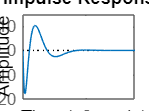

    figure (1)
    impulse(TFH);   %plot the impulse reponse

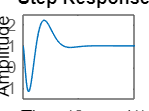

    figure(2)
    step(TFH)       %plot the step response